# Masking cyOFP

## Load images

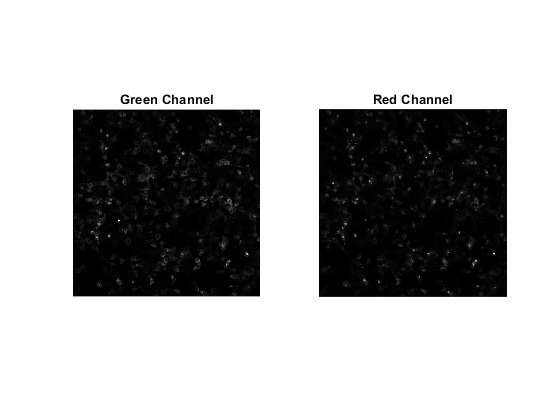

dirp = 'D:\OneDrive - Baylor College of Medicine\Paper_201906_GEVI\Fstim\20201014 Evol path';
Ig = io.nd2.read(fullfile(dirp,'JEDI-2P_P0A1-1.nd2'));
Ir = io.nd2.read(fullfile(dirp,'JEDI-2P_P0A1-2.nd2'));
figure("Name","Compare Channels");
subplot(1,2,1),imshow(Ig,[]), title('Green Channel');
subplot(1,2,2),imshow(Ir,[]), title('Red Channel');

## Background correction

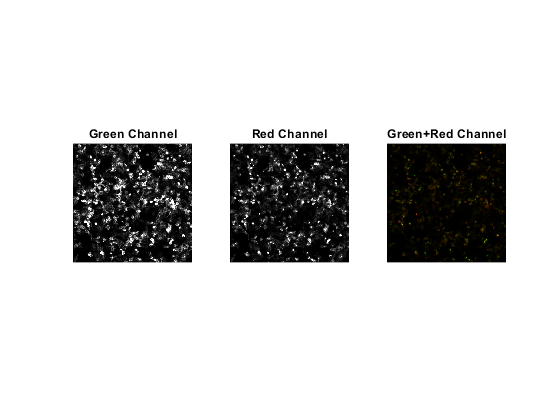

satval = 65535;
satg = (Ig == satval);
satr = (Ir == satval);
Igbgcrt = img.bgcrt(Ig, img.bglevel(img.nanmasking(Ig, ~satg), 16));
Irbgcrt = img.bgcrt(Ir, img.bglevel(img.nanmasking(Ir, ~satr), 16));
figure("Name","Compare Channels Background Corrected");
subplot(1,3,1),imshow(Igbgcrt,[0,10000]), title('Green Channel');
subplot(1,3,2),imshow(Irbgcrt,[0,4000]), title('Red Channel');
Imerge = imfuse(Igbgcrt,Irbgcrt,'falsecolor','ColorChannels',[1 2 0]);
subplot(1,3,3),imshow(Imerge,[0, 50]), title('Green+Red Channel');

## Manual mask on G and R separately

% maskg = ui.cellSel(Ig);  
% maskr = ui.cellSel(Ir);  
% imwrite(maskg, fullfile(dirp, 'MaskG.tiff'));
% imwrite(maskr, fullfile(dirp, 'MaskR.tiff'));
maskg = imread(fullfile(dirp, 'MaskG.tiff'));
maskr = imread(fullfile(dirp, 'MaskR.tiff'))

maskr = 511×512 uint16 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

maskg = maskg > 0;
maskc = maskr > 0;
maskm = maskg & ~maskr;

## CV of maskG and maskR

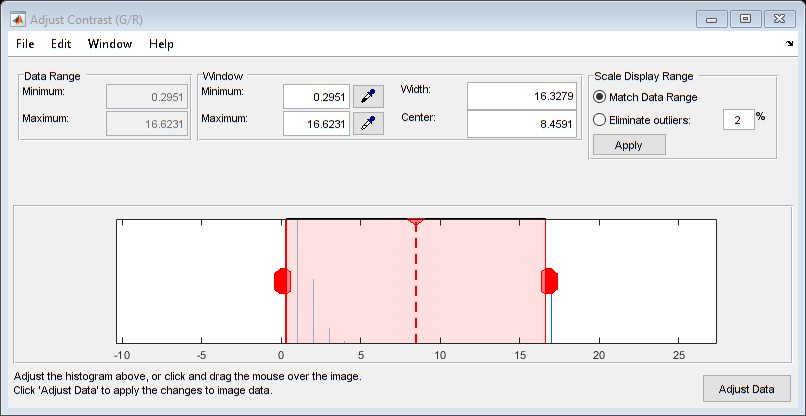

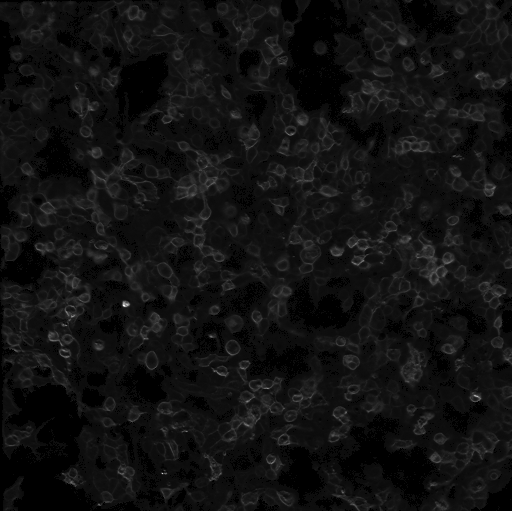

nonzeroidx = (Igbgcrt > 0) & (Irbgcrt > 0);
Igrratio = Ig.* nonzeroidx./(Ir.*nonzeroidx);
figure("Name","G/R"); imshow(Igrratio,[]);imcontrast;

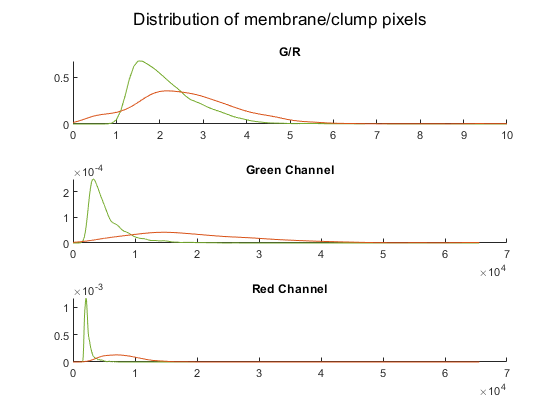

Igm = Ig(maskm);
Igc = Ig(maskc);
Irm = Ir(maskm);
Irc = Ir(maskc);
Igrm = Igrratio(maskm);
Igrc = Igrratio(maskc);
figure("Name","mask membrane"); hold on;
sgtitle('Distribution of membrane/clump pixels')
x1 = 0:0.1:10;
x2 = 0:1:65535;
subplot(3,1,1), hold on, title('G/R'),
plot(x1,pdf(fitdist(Igrm,'kernel'),x1),'Color',[0.4660, 0.6740, 0.1880]);
plot(x1,pdf(fitdist(Igrc,'kernel'),x1),'Color',[0.8500, 0.3250, 0.0980]);
subplot(3,1,2), hold on, title('Green Channel')
plot(x2,pdf(fitdist(Igm,'kernel'),x2),'Color',[0.4660, 0.6740, 0.1880]);
plot(x2,pdf(fitdist(Igc,'kernel'),x2),'Color',[0.8500, 0.3250, 0.0980]);
subplot(3,1,3), hold on, title('Red Channel')
plot(x2,pdf(fitdist(Irm,'kernel'),x2),'Color',[0.4660, 0.6740, 0.1880]);
plot(x2,pdf(fitdist(Irc,'kernel'),x2),'Color',[0.8500, 0.3250, 0.0980]);

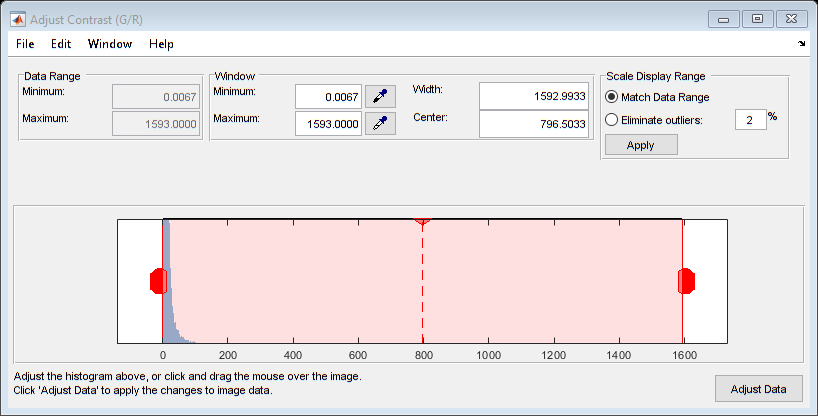

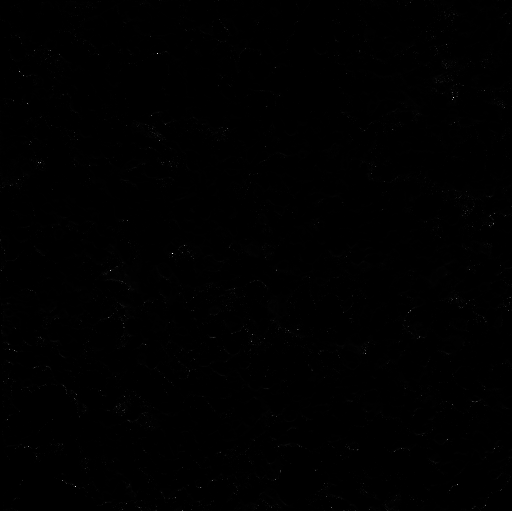

nonzeroidx = (Igbgcrt > 0) & (Irbgcrt > 0);
Igrratio = Igbgcrt.* nonzeroidx./(Irbgcrt.*nonzeroidx);
figure("Name","G/R"); imshow(Igrratio,[]);imcontrast;

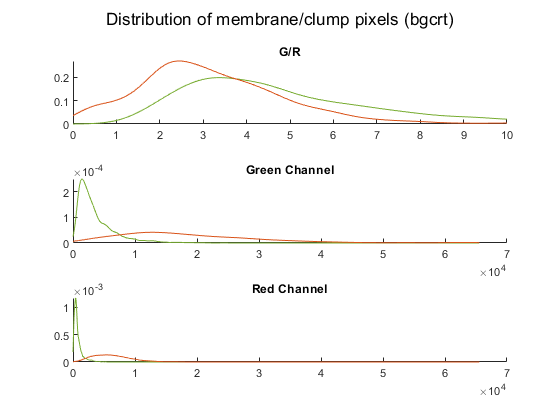

Igm = Igbgcrt(maskm);
Igc = Igbgcrt(maskc);
Irm = Irbgcrt(maskm);
Irc = Irbgcrt(maskc);
Igrm = Igrratio(maskm);
Igrc = Igrratio(maskc);
figure("Name","mask membrane"); hold on;
sgtitle('Distribution of membrane/clump pixels (bgcrt)')
x1 = 0:0.1:10;
x2 = 0:1:65535;
subplot(3,1,1), hold on, title('G/R'),
plot(x1,pdf(fitdist(Igrm,'kernel'),x1),'Color',[0.4660, 0.6740, 0.1880]);
plot(x1,pdf(fitdist(Igrc,'kernel'),x1),'Color',[0.8500, 0.3250, 0.0980]);
subplot(3,1,2), hold on, title('Green Channel')
plot(x2,pdf(fitdist(Igm,'kernel'),x2),'Color',[0.4660, 0.6740, 0.1880]);
plot(x2,pdf(fitdist(Igc,'kernel'),x2),'Color',[0.8500, 0.3250, 0.0980]);
subplot(3,1,3), hold on, title('Red Channel')
plot(x2,pdf(fitdist(Irm,'kernel'),x2),'Color',[0.4660, 0.6740, 0.1880]);
plot(x2,pdf(fitdist(Irc,'kernel'),x2),'Color',[0.8500, 0.3250, 0.0980]);